**Types of Smoothening Filters**

1. Smoothing Linear Filters -------

                      a) Average Filter

                      b) Weighted Filter

2. Smoothing Non-Linear Filters -------

                       a) Median Filter

## I. Average Filtering:

The output of a smoothing, linear spatial filter is simply the average of the pixels contained in the neighborhood of the filter mask. These filters sometimes are called averaging filters. For reasons explained in they also are referred to a low pass filters. The idea behind smoothing filters is straightforward. By replacing the value of every pixel in an image by the average of the gray levels in the neighborhood defined by the filter mask, this process results in an image with reduced “sharp” transitions in gray levels. Because random noise typically consists of sharp transitions in gray levels, the most obvious application of smoothing is noise reduction.

Average Filter mask is as follows:

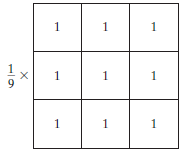

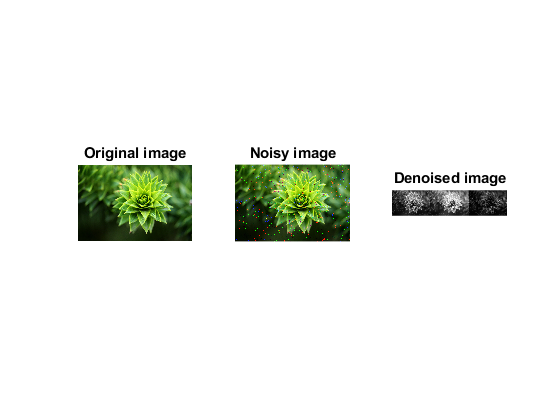

% Read Image for Noise Addition
img=imread('fractal.jpg');
% Add Noise
Noi_img = imnoise(img,'salt & pepper', 0.02);
% Mask Definition
f=1/9*[1,1,1;1,1,1;1,1,1];

% Apply filter2 function
de_noi=filter2(f,Noi_img);
figure;
subplot(1,3,1);imshow(img);title('Original image')
subplot(1,3,2);imshow(Noi_img);title('Noisy image')
subplot(1,3,3);imshow(uint8(de_noi));title('Denoised image')

## II. Weighted Filtering:

## The second mask is a little more interesting. This mask yields a so-called weighted average, terminology used to indicate that pixels are multiplied by different coefficients, thus giving more importance (weight) to some pixels at the expense of others. In the mask the pixel at the center of the mask is multiplied by a higher value than any other, thus giving this pixel more importance in the calculation of the average.

Weighted Filter mask is as follows:

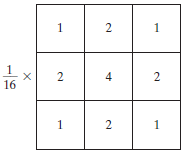

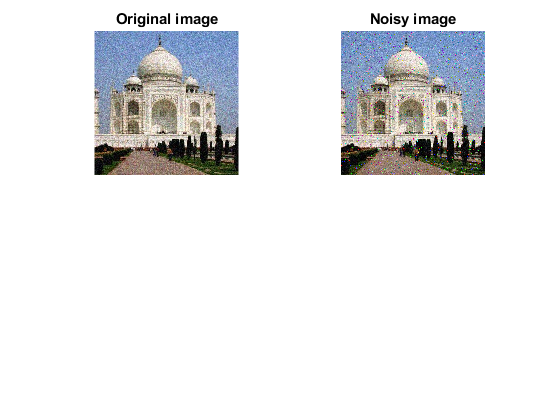

% Read Image for Noise Addition
img=imread('taj-noise.jpg');
% Add Noise
Noi_img = imnoise(img,'salt & pepper', 0.02);
% Mask Definition
f=1/16*[1,2,1;2,4,2;1,2,1];

% Apply filter2 function
de_noi=filter2(f,Noi_img);
figure;
subplot(2,2,1);imshow(img);title('Original image')
subplot(2,2,2);imshow(Noi_img);title('Noisy image')

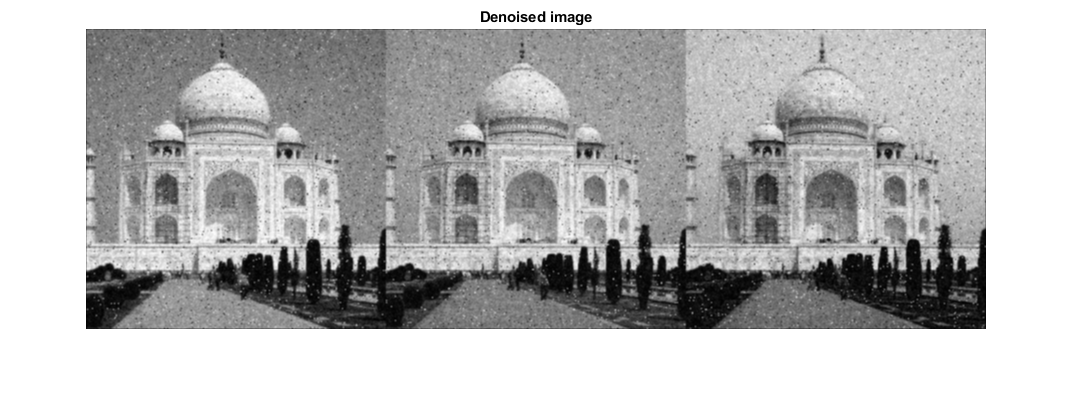

subplot(1,1,1);imshow(uint8(de_noi));title('Denoised Weighted Filtered Image')

## III. Median Filtering

## The best-known example in this category is the median filter, which, as its name implies, replaces the value of a pixel by the median of the gray levels in the neighborhood of that pixel (the original value of the pixel is included in the computation of the median). Median filters are quite popular because, for certain types of random noise, they provide excellent noise-reduction capabilities, with considerably less blurring than linear smoothing filters of similar size. Median filters are particularly effective in the presence of impulse noise, also called salt-and-pepper noise because of its appearance as white and black dots superimposed on an image.

% Read Image for Noise Addition
img=imread('taj-noise.jpg');
% Add Noise
img = rgb2gray(img)

img = 300×300 uint8 matrix
   130   121   147   159   112   138   133   130   146   149   126   138   159   129   170   142   141   115   157   154   128   130   120   146   125   132   157   128   133   149   126   133   167   155   116   149   159   135   158   153   168   122   137   142   131   160   152   159   122   124
   134   147   117   141   173   134   126   140   114   136   126   109   123   111   134   127   107   190   138   151   112   115   164   151   138   112   130   116   169   155   139   149   137   163   160   160   130   175   148   120   130   154   112   135   117   156   119   164   137   124
   125   146   151    97   130   149   126   148   126   138   125   142   148   160   127   142   156   165   142   145   123   133   103   106   158   117   122   132   126   154   130   127   124   139   153   126   138   127   142   124   158   113   164   166   120   123   145   117   149   152
   157   137   186   163   136   135   199   158   143   139   128   1

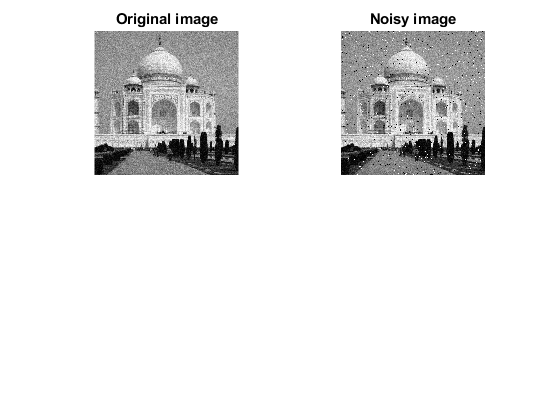

Noi_img = imnoise(img,'salt & pepper', 0.02);
% Mask Definition

% Generating an averaging filter
h_average = fspecial('average', 3);

% Generate a Gaussian Filter
h_gaussian = fspecial('gaussian', 3,0.5);

A_average = imfilter(Noi_img, h_average);
A_gaussian = imfilter(Noi_img, h_gaussian);

% Apply filter2 function
de_noi=medfilt2(img);

figure;
subplot(2,2,1);imshow(img);title('Original image')
subplot(2,2,2);imshow(Noi_img);title('Noisy image')

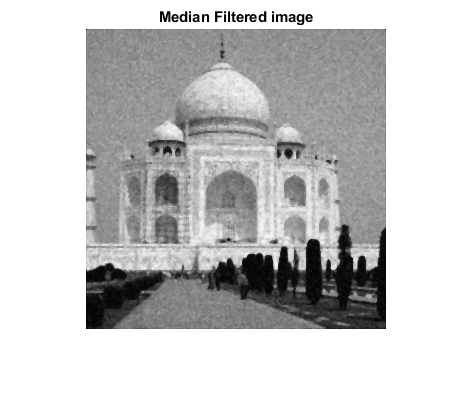

subplot(1,1,1);imshow(uint8(de_noi));title('Median Filtered image')